## Step 1: Read and display the image

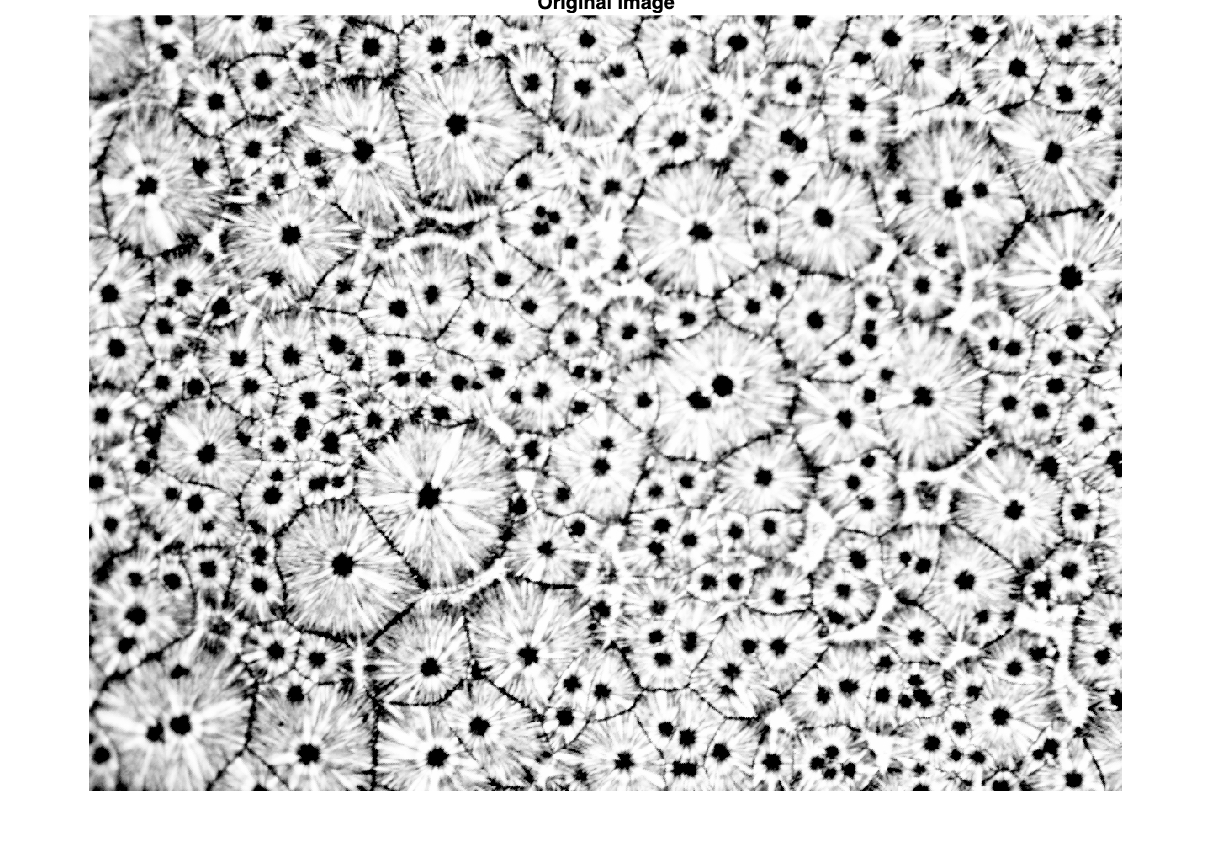

img = imread('0.35 M SnO2  60 m min 50 O oC 3 CB S.jpg');

figure;
imshow(img);
title('Original Image');

## Step 2: Convert to grayscale

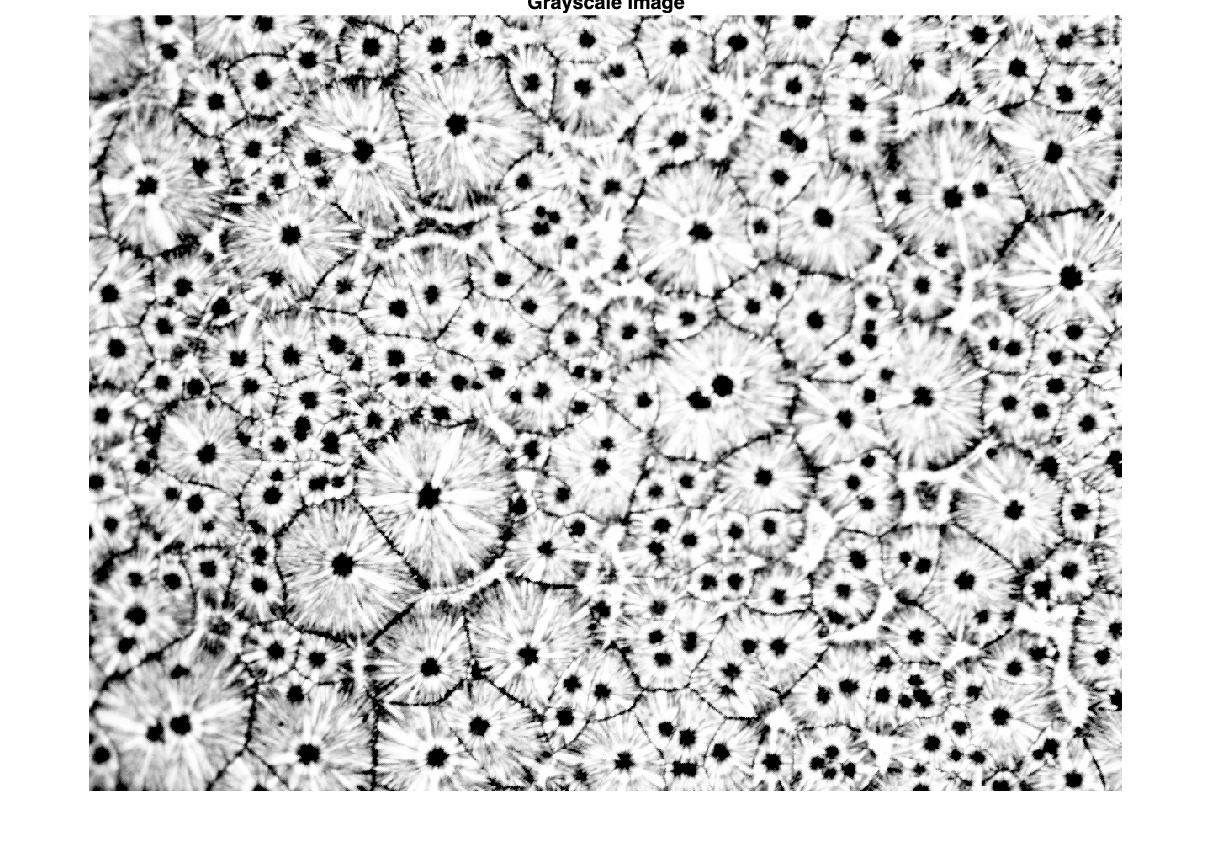

gray_img = rgb2gray(img);

figure;
imshow(gray_img);
title('Grayscale Image');

## Step 3: Apply a threshold to isolate the black dots (adjust threshold level as needed)

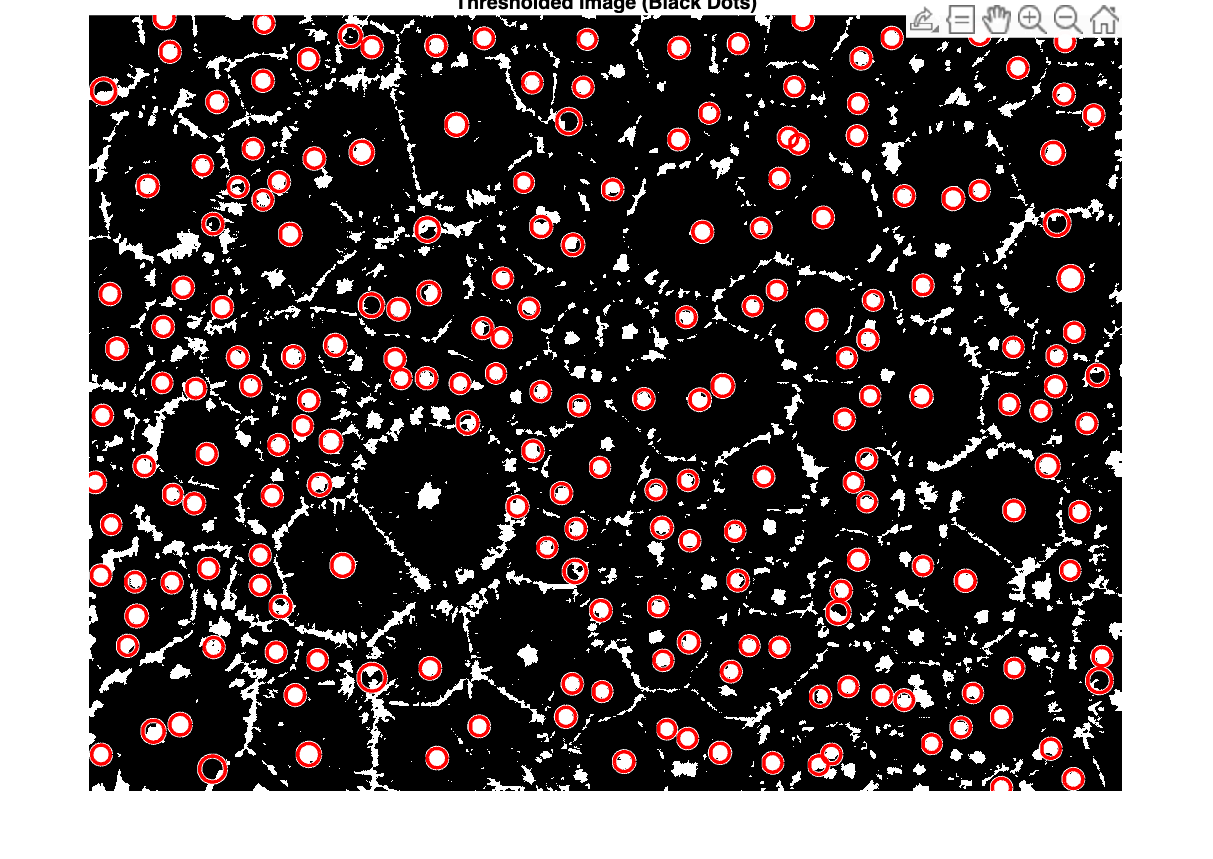

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


threshold_value = 100;  % You can adjust this based on your image
bw_img = gray_img < threshold_value;  % Black dots assumed on a lighter background

imshow(bw_img);
title('Thresholded Image (Black Dots)');

% Specify the range of radius you expect for the circles
[centers, radii] = imfindcircles(bw_img, [10 20], 'ObjectPolarity', 'bright', 'Sensitivity', 0.9);
% Plot bright circles in blue
viscircles(centers, radii)%,'Color','b');

## Step 4: Crop the image to make it square (use the smaller dimension)

[height, width, ~] = size(bw_img);  % Get the image dimensions
new_dim = min(height, width);  % Get the smaller dimension
crop_x_start = floor((width - new_dim) / 2) + 1;  % Starting x-coordinate for cropping
crop_y_start = floor((height - new_dim) / 2) + 1;  % Starting y-coordinate for cropping
cropped_img = bw_img(crop_y_start:crop_y_start + new_dim - 1, crop_x_start:crop_x_start + new_dim - 1, :);

% Display the cropped image
figure;
imshow(cropped_img);
title('Cropped Square Image');

## Step 5: Compute the 2D FFT of the thresholded binary image

fft_img = fftshift(fft2(cropped_img));

% Get the magnitude of the FFT
fft_magnitude = abs(fft_img);

figure;
imshow(log(1 + fft_magnitude), []);
title('2D FFT Magnitude');
hold on;  % To overlay the circle on the image

% FFT image size and center
[rows, cols] = size(fft_magnitude);
center = [rows/2, cols/2];

% Step 6: Define a circular region
radius = min(height, width)/2 - 50;  % Adjust radius based on the desired circle size

% Create a grid of (x,y) coordinates
[x_grid, y_grid] = meshgrid(1:cols, 1:rows);

% Compute the distance from the center to each point
dist_from_center = sqrt((x_grid - center(2)).^2 + (y_grid - center(1)).^2);

% Mask for points that lie inside the circle
circle_mask = dist_from_center <= radius;  % Points inside the circle


% Overlay the circle on the FFT magnitude image
theta = linspace(0, 2*pi, 100);
x_circle = radius * cos(theta) + center(2);
y_circle = radius * sin(theta) + center(1);

% Plot the circle on top of the FFT image
plot(x_circle, y_circle, 'r', 'LineWidth', 2); hold off;
title('2D FFT Magnitude with Circular Overlay');


## Step 6: Calculate angles and magnitudes inside the circle

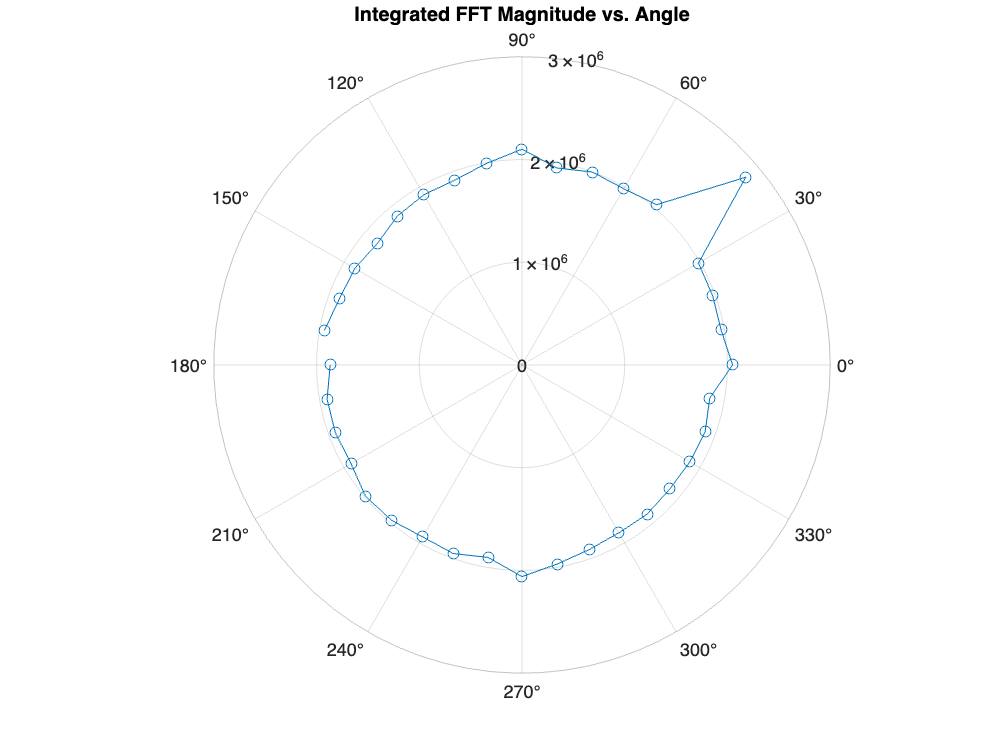

circle_fft_magnitude = fft_magnitude(circle_mask);

% Get the (x,y) coordinates of points inside the circle
circle_x = x_grid(circle_mask);
circle_y = y_grid(circle_mask);

% Compute the angle for each point inside the circle
angles = atan2d(circle_y - center(1), circle_x - center(2));  % Angle in degrees

% Bin the angles into 360 angular bins
bin_edges = -180:10:180;  % 1-degree bins from -180 to 180 degrees
[angle_bin_counts, ~, angle_bin_indices] = histcounts(angles, bin_edges);

% Sum the FFT magnitudes within each angular bin
angle_bin_sums = accumarray(angle_bin_indices, circle_fft_magnitude);

% Step 9: Plot the magnitude vs angle
figure;
polarplot(deg2rad(bin_edges(1:end-1)), angle_bin_sums, '-o');
title('Integrated FFT Magnitude vs. Angle');